## Example of Matlab Live Script

Here, let us illustrate how a live script works. A live script provides for a level of interaction that a regular script does not.

### Equation of projectile motion

Let us assume that the x-axis is the horizontal ground and the y axis points upwards. We have a projectile, with initial position $(x_{0},y_{0})=(0,0)$ and with initial speed of V and an initial angle (relative to the ground) of $\theta$. The horizontal and vertical position of the projectile are given by (assuming no air resistance)


$$x(t) = V\cos(\theta)\;t$$



$$y(t)=V\sin(\theta)\; t -\frac{1}{2}gt^{2}$$


where g is the gravitational acceleration. Therefore, the trajectory is controlled by the initial speed and the launch angle. If you are curious about how I inserted equations, please to go the *insert* tab and click on the *equation* option. You can use an equation editor (much like found in MS Word), or you can choose to insert an equation using [LaTeX](https://www.overleaf.com/learn/latex/Mathematical_expressions) commands. Note also that you can include hyperlinks (see previous sentence).

### Interactive plot

Below, select V (m/s) and $\theta$ (deg). Note: it's pretty cool that you can insert interactive [controls](https://www.mathworks.com/help/matlab/matlab_prog/add-interactive-controls-to-a-live-script.html) like the sliders below. Again, see the *insert* menu and look for the *control* drop-down box. 

%define the parameters
V = 7.8 

V = 7.8000

theta = 31

theta = 31

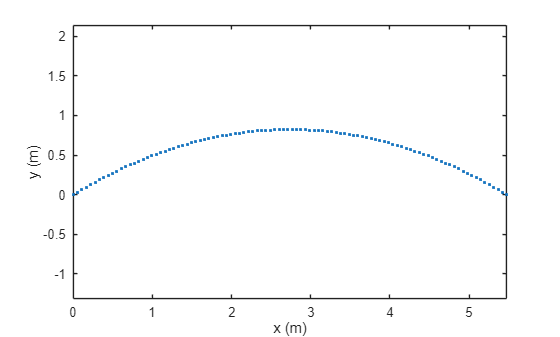

g = 9.81;    %gravity in SI units
%solve for final time
tf=2*V*sind(theta)/g;
t=linspace(0,tf,100);
x=V*cosd(theta)*t;
y=V*sind(theta)*t-1/2*g*t.^2;
figure(1)
set(gcf,'PaperPosition',[1,1,1,1])
plot(x,y,'.');
xlabel('x (m)'); ylabel('y (m)'); axis equal; 